
file_path1 = 'C:\Users\gajapathy.s\Desktop\data_processing\imu\LocationC\5hour.xlsx';
file_path2 = 'C:\Users\gajapathy.s\Desktop\data_processing\imu\LocationC\five_hour.bag';

bag = rosbag(file_path2);
bSel = select(bag,'Topic','/vectornav')

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\gajapathy.s\Desktop\data_processing\imu\LocationC\five_hour.bag'
          StartTime: 1.6768e+09
            EndTime: 1.6768e+09
        NumMessages: 719907
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [719907×4 table]


msgStructs = readMessages(bSel,'DataFormat','struct');
t=cellfun(@(m) double(m.Header.Stamp.Sec),msgStructs);
ns=cellfun(@(m) double(m.Header.Stamp.Nsec),msgStructs);

nano_sec=ns.*(1e-9);
time=t+nano_sec;
time=time-time(1);

len=bSel.NumMessages;

l=1:1:len;

S_time=bSel.StartTime;
E_time=bSel.EndTime;

delta_time=E_time-S_time;

fields=readtable(file_path1);

Y=fields(:,2);
yaw= Y.*(pi/180);
P=fields(:,3);
pitch= P.*(pi/180);
R=fields(:,4);
roll= R.*(pi/180);




h_y=table2array(yaw./2);
h_p=table2array(pitch./2);
 h_r=table2array(roll./2);


DCM = [
    cosd(h_p) .* cosd(h_y), cosd(h_p) .* sind(h_y), -sind(h_p);
    -sind(h_r).* sind(h_p) .* cosd(h_y) + cosd(h_r) .* sind(h_y), cosd(h_r) .* cosd(h_y) + sind(h_r) .* sind(h_p) .* sind(h_y), cosd(h_p) .* sind(h_r);
    cosd(h_r).* sind(h_p) .* cosd(h_y) + sind(h_r) .* sind(h_y), -cosd(h_r) .* sind(h_y) + sind(h_r) .* sind(h_p) .* cosd(h_y), cosd(h_p) .* cosd(h_r)
];


orientation_x = 0.25 * sqrt(1 + DCM(1, 1) - DCM(2, 2) - DCM(3, 3));
orientation_y = 0.25 * sqrt(1 - DCM(1, 1) + DCM(2, 2) - DCM(3, 3));
orientation_z = 0.25 * sqrt(1 - DCM(1, 1) - DCM(2, 2) + DCM(3, 3));
orientation_w = 0.25 * sqrt(1 + DCM(1, 1) + DCM(2, 2) + DCM(3, 3));








% orientation_w = ((cos(h_y) .* cos(h_p).* cos(h_r))) + ((sin(h_y)).* sin(h_p).* sin(h_r));
% orientation_x =((cos(h_y) .* sin(h_p).* cos(h_r)) - (sin(h_y).* cos(h_p).* sin(h_r)));
% orientation_y =((cos(h_y) .* cos(h_p) .* sin(h_r)) + (sin(h_y).* sin(h_p).* cos(h_r)));
% orientation_z = ((sin(h_y).* sin(h_p).* cos(h_r)) - (cos(h_y).* sin(h_p).* sin(h_r)));



magnetic_field_x=table2array(fields(:,5).*0.0001);
magnetic_field_y=table2array(fields(:,6).*0.0001);
magnetic_field_z=table2array(fields(:,7).*0.0001);

linear_acceleration_x=table2array(fields(:,8));
linear_acceleration_y=table2array(fields(:,9));
linear_acceleration_z=table2array(fields(:,10));


angular_velocity_x=table2array(fields(:,11));
angular_velocity_y=table2array(fields(:,12));
angular_velocity_z_string = fields(:,13);

a = table2array(angular_velocity_z_string);



for i = 1:numel(angular_velocity_z_string)
    part_before_asterisk{i} = regexp(a{i}, '([^*]+)', 'match', 'once');
end

angular_velocity_z=part_before_asterisk;




angular_velocity_x_rad_sec=angular_velocity_x.*(180/pi);
angular_velocity_y_rad_sec=angular_velocity_y.*(180/pi);
angular_velocity_z_rad_sec=str2double(angular_velocity_z).*(180/pi);













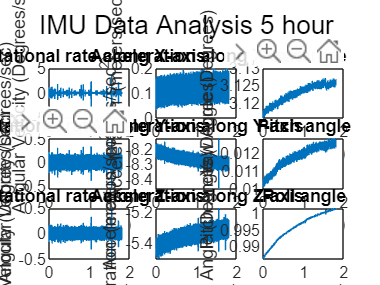

clear title


figure;

subplot(3,3,1)
plot(time, angular_velocity_x_rad_sec)
title("Rotational rate along X-axis")
xlabel("Time (sec)")
ylabel("Angular Velocity (Degrees/sec)")

subplot(3,3,4)
plot(time, angular_velocity_y_rad_sec)
title('Rotational rate along Y-axis')
xlabel("Time (sec)")
ylabel("Angular Velocity (Degrees/sec)")

subplot(3,3,7)
plot(time, angular_velocity_z_rad_sec)
title('Rotational rate along Z-axis')
xlabel("Time (sec)")
ylabel("Angular Velocity (Degrees/sec)")


subplot(3,3,2)
plot(time, linear_acceleration_x)
title("Acceleration along X-axis")
xlabel("Time (sec)")
ylabel("Acceleration (meters/sec^2)")

subplot(3,3,5)
plot(time, linear_acceleration_y)
title("Acceleration along Y-axis")
xlabel("Time (sec)")
ylabel("Acceleration (meters/sec^2)")

subplot(3,3,8)
plot(time, linear_acceleration_z)
title("Acceleration along Z-axis")
xlabel("Time (sec)")
ylabel("Acceleration (meters/sec^2)")


subplot(3,3,3)
plot(time, table2array(yaw))
title("Yaw angle")
xlabel("Time (sec)")
ylabel("Yaw Angle (Degrees)")

subplot(3,3,6)
plot(time, table2array(pitch))
title("Pitch angle")
xlabel("Time (sec)")
ylabel("Pitch Angle (Degrees)")

subplot(3,3,9)
plot(time, table2array(roll))
title("Roll angle")
xlabel("Time (sec)")
ylabel("Roll Angle (Degrees)")


% sgtitle('IMU Data Analysis 5 hour ');

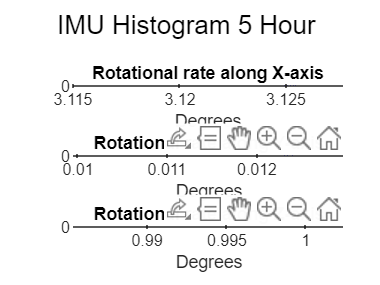

 figure
subplot(3,1,1)
histogram(table2array(yaw), 500, 'FaceColor', 'b', 'EdgeColor', 'k')
title("Rotational rate along X-axis")
ylabel("Data points")
xlabel("Degrees")
subplot(3,1,2)
histogram(table2array(pitch), 500, 'FaceColor', 'b', 'EdgeColor', 'k')
title("Rotational rate along Y-axis")
ylabel("Data points")
xlabel("Degrees")
subplot(3,1,3)
histogram(table2array(roll), 500, 'FaceColor', 'b', 'EdgeColor', 'k')
title("Rotational rate along Z-axis")
ylabel("Data points")
xlabel("Degrees")

sgtitle('IMU Histogram 5 Hour ');